**Author** : Kelebogile Mathole

**PhD Studen**t : University of Pretoria (South Africa)

**Supervisor (s) **: T. Ndarana, T Shephered and M-J Bopape

**Projec**t : MATHEMATICS OF PLANET EARTH CENTRE FOR DOCTORAL TRAINING

VIRTUAL SUMMER SCHOOL “Forecast verification”

June 21-25, 2021

# **PROJECT 4**: Verification of 2 metre temperature (2mt) ensemble seasonal forecasts

# **Goal**: To compare and contrast the forecasts from the three models

**Introduction:**

DEMETER (Development of a European Multimodel Ensemble system for seasonal to inTERannual prediction) is an EU initiative to develop a well-validated European multi-model ensemble forecast system for reliable seasonal to inter-annual prediction. It ran from 2000-2003. (SEE Palmer et al, BAMS, 85, 853-872 for further details of the project, and also on the ECMWF.int website). This project offers the opportunity to compare the quality of three 9-member ensembles for three-month average temperature forecasts.

**Data files**:

t2m-ecmwf-JJA-1959-2001.txt, t2m-mf-JJA-1959-2001.txt and t2m-ukmo-JJA-1959-2001.txt. These files contain 1-month lead 2 metre temperature (2mt) forecasts produced in May and valid for JJA for the period 1959-2001 (i.e. 43-years of forecasts) for a grid point in central Pacific (latitude 0o, longitude 140oW) for three coupled seasonal forecast models which were included in the DEMETER project (ECMWF, Meteo-France, and UK Met Office). The structure of the data files is as follows: (There is no header row) 1st column: year 2nd column: “observed” 2mt in JJA (from ERA-40 reanalysis) 3rd to 11th column: forecast JJA 2mt (ensemble member 1 to 9)

clear all
close all

%loading model(s) data
t2m_ecmwf = load('data/raw/Proj4_t2m-ecmwf-JJA-1959-2001.txt');
t2m_mf = load('data/raw/Proj4_t2m-mf-JJA-1959-2001.txt');
t2m_ukmo = load('data/raw/Proj4_t2m-ukmo-JJA-1959-2001.txt');


**Analysis suggestions**:

These are ensemble forecasts (9 ensemble members for each forecast), so can be used to estimate the probability of departure from the normal (climatological) mean temperature or the probabilities for tercile categories (below normal, normal, above normal) for the three month period. *The climatological mean can be defined by the average of the observations for the 43 years. The distribution of the observations can then be used to define quantiles e,g below normal, normal and above normal with thresholds at the 33rd, and 67th percentiles of the observed distribution.*

It is customary to account for the bias in the models when carrying out the verification. This is done by using the whole ensemble of forecasts (9 members for all 43 years, total 387 temperature values) to compute tercile thresholds of temperature. This is done separately for each of the 3 models. Then probabilities of below normal, normal and above normal can be determined for each ensemble for each of the 43 years by counting the number of ensemble members falling in each tercile category and dividing by the total number of ensemble members (9), using the respective model tercile thresholds, and verified according to the methods of probability verification for discrete probability distributions. (RPS, RPSS, etc). The verification can also be done by considering two- two-category predictions, for P(upper tercile) vs (not upper tercile) and P(lower tercile) vs (not lower tercile). In this case the BS and BSS are the appropriate scores. (Note that the RPS and the BS are equal for two categories)

The forecasts can also be verified using contingency tables, either a 3 by 3 or two- two-category tables with thresholds at 33 and 67%, highest probability category is chosen as the predicted category.

# **Suggested steps:**

# 1. Plot the ensemble mean vs the observation for each model. This offers a quick assessment of bias.

ECMWF Model

years = 1959:2001

years =         1959        1960        1961        1962        1963        1964        1965        1966        1967        1968        1969        1970        1971        1972        1973        1974        1975        1976        1977        1978        1979        1980        1981        1982        1983        1984        1985        1986        1987        1988        1989        1990        1991        1992        1993        1994        1995        1996        1997        1998        1999        2000        2001



% loading esm members and compute the ens mean for each year
ens_mean_ecmwf = nan(1,43);
for yr = 1:43   
    ens_ecmwf = t2m_ecmwf(yr,3:end);
    data = mean(t2m_ecmwf(yr,3:end),2,'omitnan');
    ens_mean_ecmwf(:,yr) = mean(t2m_ecmwf(yr,3:end),2,'omitnan');
end

ens_mean_ecmwf = ens_mean_ecmwf'

ens_mean_ecmwf =    26.0640
   26.0735
   25.5560
   25.0041
   25.9674
   23.6016
   25.7442
   25.2208
   24.9882
   24.8039



% loading the era40 obs
era40_obs = t2m_ecmwf(:,2:2)

era40_obs =    25.5126
   25.9715
   25.7935
   25.7818
   26.9272
   25.2311
   27.1308
   25.7444
   25.8433
   26.7130



% plotting 
fig = figure('pos',[80 80 1000 500])

fig =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [80 80 1000 500]
       Units: 'pixels'

  Show all properties


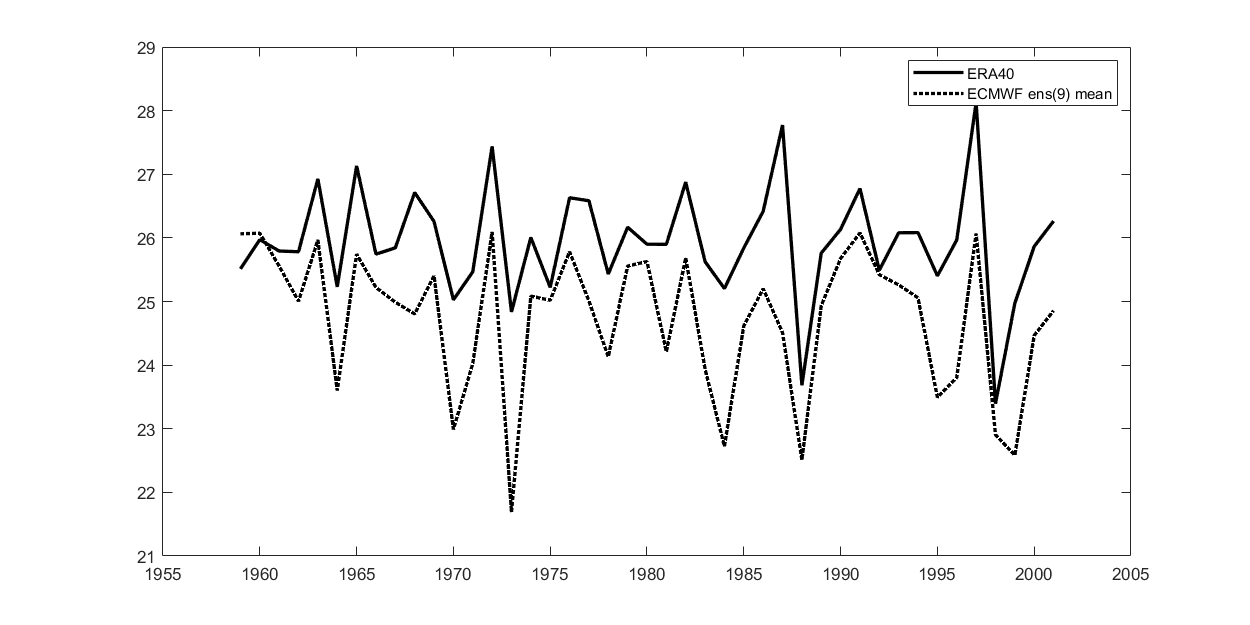

plot(years,era40_obs,'color','k','linewidth',2.0)
hold on
plot(years,ens_mean_ecmwf,'color','k','linestyle',':','linewidth',2.0)
legend("ERA40","ECMWF ens(9) mean");ylim([21 29])

title('Obs vs. ECMWF')

METEO France Model

ens_mean_mf = nan(1,43);
for yr = 1:43   
    ens_mf = t2m_mf(yr,3:end);
    data = mean(t2m_mf(yr,3:end),2,'omitnan');
    ens_mean_mf(:,yr) = mean(t2m_mf(yr,3:end),2,'omitnan');
end

ens_mean_mf = ens_mean_mf'

ens_mean_mf =    26.0843
   26.5242
   26.2595
   26.0345
   26.9652
   24.9218
   26.4523
   26.0561
   26.1381
   26.1045



% loading the era40 obs
era40_obs = t2m_mf(:,2:2)

era40_obs =    25.5126
   25.9715
   25.7935
   25.7818
   26.9272
   25.2311
   27.1308
   25.7444
   25.8433
   26.7130



% plotting 
fig = figure('pos',[80 80 1000 500])

fig =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [80 80 1000 500]
       Units: 'pixels'

  Show all properties


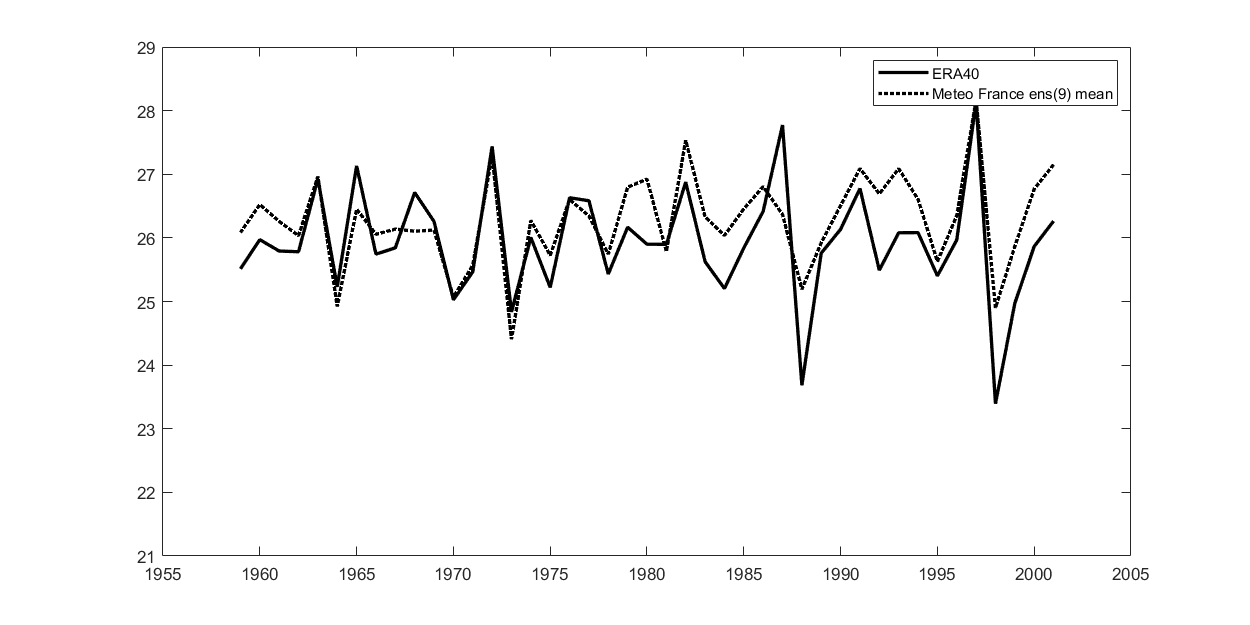

plot(years,era40_obs,'color','k','linewidth',2.0)
hold on
plot(years,ens_mean_mf,'color','k','linestyle',':','linewidth',2.0)
legend("ERA40","Meteo France ens(9) mean");ylim([21 29])

title('Obs vs. Meteo France')


UKMO Model 

ens_mean_ukmo = nan(1,43);
for yr = 1:43   
    ens_ukmo = t2m_ukmo(yr,3:end);
    data = mean(t2m_ukmo(yr,3:end),2,'omitnan');
    ens_mean_ukmo(:,yr) = mean(t2m_ukmo(yr,3:end),2,'omitnan');
end

ens_mean_ukmo = ens_mean_ukmo';

ens_mean_ukmo =    25.8523
   25.2874
   25.1275
   24.2970
   25.7403
   22.2282
   25.6997
   24.6147
   25.1063
   24.2573



% loading the era40 obs
era40_obs = t2m_ukmo(:,2:2);

era40_obs =    25.5126
   25.9715
   25.7935
   25.7818
   26.9272
   25.2311
   27.1308
   25.7444
   25.8433
   26.7130



% plotting 
fig = figure('pos',[80 80 1000 500])

fig =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [80 80 1000 500]
       Units: 'pixels'

  Show all properties


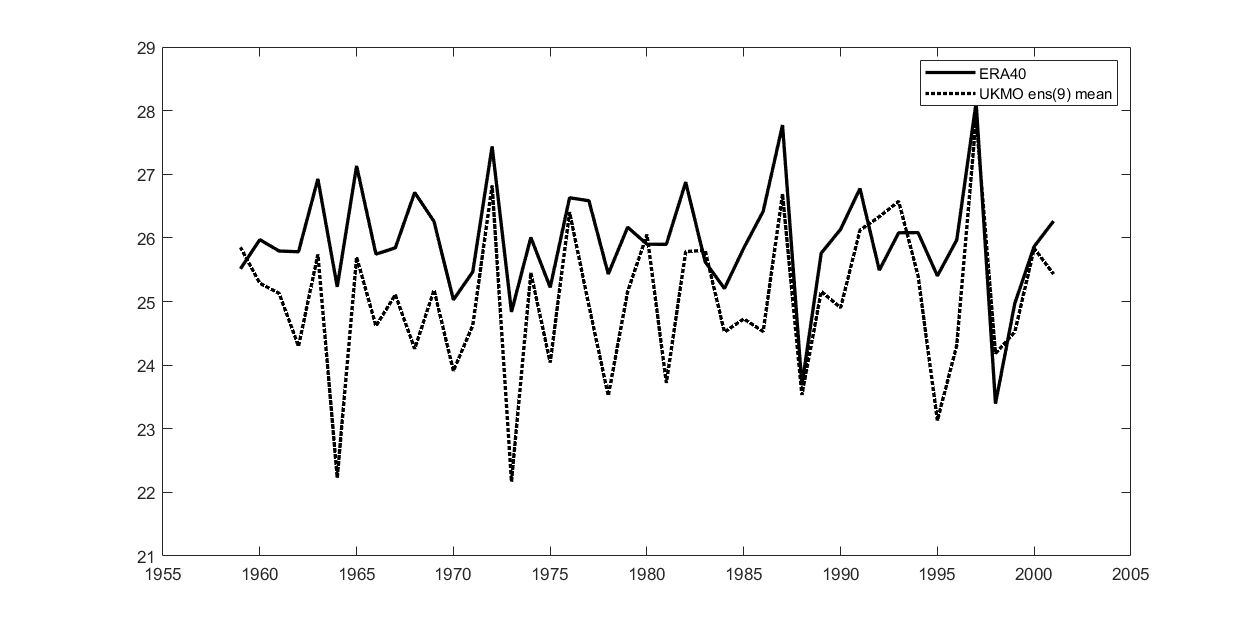

plot(years,era40_obs,'color','k','linewidth',2.0)
hold on
plot(years,ens_mean_ukmo,'color','k','linestyle',':','linewidth',2.0)
legend("ERA40","UKMO ens(9) mean");ylim([21 29])

title('Obs vs. UKMO')


# 2. Compute the temperature tercile threshold values for the observations (from the 43-member distribution of observations) and for each of the models. (from the 387 member grand ensemble of forecasts)

Terciles threshold values for Observations

clim_mean_obs = mean(era40_obs,"all","omitnan")

clim_mean_obs = 25.9363

upper_terc_obs = quantile(era40_obs,0.67,"all")

upper_terc_obs = 26.1449

lower_terc_obs = quantile(era40_obs,0.33,"all")

lower_terc_obs = 25.7077

Terciles threshold values for each model and each ensemble (9)?

% ECMWF model

all_ens_upper_terc_ecmwf = [];
all_ens_lower_terc_ecmwf = [];
for es = 3:11   
    upper_terc_ecmwf = quantile(t2m_ecmwf(:,es),0.67,"all");
    lower_terc_ecmwf = quantile(t2m_ecmwf(:,es),0.33,"all");
    all_ens_upper_terc_ecmwf = vertcat(all_ens_upper_terc_ecmwf,upper_terc_ecmwf)
    all_ens_lower_terc_ecmwf = vertcat(all_ens_lower_terc_ecmwf,lower_terc_ecmwf)
end

all_ens_upper_terc_ecmwf = 25.2304

all_ens_lower_terc_ecmwf = 24.1790

all_ens_upper_terc_ecmwf =    25.2304
   25.4470


all_ens_lower_terc_ecmwf =    24.1790
   24.5685


all_ens_upper_terc_ecmwf =    25.2304
   25.4470
   25.6601


all_ens_lower_terc_ecmwf =    24.1790
   24.5685
   24.4074


all_ens_upper_terc_ecmwf =    25.2304
   25.4470
   25.6601
   25.4367


all_ens_lower_terc_ecmwf =    24.1790
   24.5685
   24.4074
   24.3319


all_ens_upper_terc_ecmwf =    25.2304
   25.4470
   25.6601
   25.4367
   25.5361


all_ens_lower_terc_ecmwf =    24.1790
   24.5685
   24.4074
   24.3319
   24.7142


all_ens_upper_terc_ecmwf =    25.2304
   25.4470
   25.6601
   25.4367
   25.5361
   25.6204


all_ens_lower_terc_ecmwf =    24.1790
   24.5685
   24.4074
   24.3319
   24.7142
   24.3934


all_ens_upper_terc_ecmwf =    25.2304
   25.4470
   25.6601
   25.4367
   25.5361
   25.6204
   25.2478


all_ens_lower_terc_ecmwf =    24.1790
   24.5685
   24.4074
   24.3319
   24.7142
   24.3934
   24.5008


all_ens_upper_terc_ecmwf =    25.2304
   25.4470
   25.6601
   25.4367
   25.5361
   25.6204
   25.2478
   25.5113


all_ens_lower_terc_ecmwf =    24.1790
   24.5685
   24.4074
   24.3319
   24.7142
   24.3934
   24.5008
   24.5723


all_ens_upper_terc_ecmwf =    25.2304
   25.4470
   25.6601
   25.4367
   25.5361
   25.6204
   25.2478
   25.5113
   25.6124


all_ens_lower_terc_ecmwf =    24.1790
   24.5685
   24.4074
   24.3319
   24.7142
   24.3934
   24.5008
   24.5723
   24.5960




% MF model

all_ens_upper_terc_mf = [];
all_ens_lower_terc_mf = [];
for es = 3:11   
    upper_terc_mf = quantile(t2m_mf(:,es),0.67,"all");
    lower_terc_mf = quantile(t2m_mf(:,es),0.33,"all");
    all_ens_upper_terc_mf = vertcat(all_ens_upper_terc_mf,upper_terc_mf)
    all_ens_lower_terc_mf = vertcat(all_ens_lower_terc_mf,lower_terc_mf)
end

all_ens_upper_terc_mf = 26.6163

all_ens_lower_terc_mf = 25.9278

all_ens_upper_terc_mf =    26.6163
   26.7807


all_ens_lower_terc_mf =    25.9278
   26.1077


all_ens_upper_terc_mf =    26.6163
   26.7807
   26.7010


all_ens_lower_terc_mf =    25.9278
   26.1077
   25.9945


all_ens_upper_terc_mf =    26.6163
   26.7807
   26.7010
   26.6990


all_ens_lower_terc_mf =    25.9278
   26.1077
   25.9945
   25.9128


all_ens_upper_terc_mf =    26.6163
   26.7807
   26.7010
   26.6990
   26.4462


all_ens_lower_terc_mf =    25.9278
   26.1077
   25.9945
   25.9128
   25.7694


all_ens_upper_terc_mf =    26.6163
   26.7807
   26.7010
   26.6990
   26.4462
   26.6061


all_ens_lower_terc_mf =    25.9278
   26.1077
   25.9945
   25.9128
   25.7694
   25.9280


all_ens_upper_terc_mf =    26.6163
   26.7807
   26.7010
   26.6990
   26.4462
   26.6061
   26.7329


all_ens_lower_terc_mf =    25.9278
   26.1077
   25.9945
   25.9128
   25.7694
   25.9280
   25.9344


all_ens_upper_terc_mf =    26.6163
   26.7807
   26.7010
   26.6990
   26.4462
   26.6061
   26.7329
   26.6804


all_ens_lower_terc_mf =    25.9278
   26.1077
   25.9945
   25.9128
   25.7694
   25.9280
   25.9344
   25.9891


all_ens_upper_terc_mf =    26.6163
   26.7807
   26.7010
   26.6990
   26.4462
   26.6061
   26.7329
   26.6804
   26.7267


all_ens_lower_terc_mf =    25.9278
   26.1077
   25.9945
   25.9128
   25.7694
   25.9280
   25.9344
   25.9891
   25.8751




% UKMO model

all_ens_upper_terc_ukmo = [];
all_ens_lower_terc_ukmo = [];
for es = 3:11   
    upper_terc_ukmo = quantile(t2m_ukmo(:,es),0.67,"all");
    lower_terc_ukmo = quantile(t2m_ukmo(:,es),0.33,"all");
    all_ens_upper_terc_ukmo = vertcat(all_ens_upper_terc_ukmo,upper_terc_ukmo)
    all_ens_lower_terc_ukmo = vertcat(all_ens_lower_terc_ukmo,lower_terc_ukmo)
end

all_ens_upper_terc_ukmo = 25.5082

all_ens_lower_terc_ukmo = 24.6927

all_ens_upper_terc_ukmo =    25.5082
   25.5533


all_ens_lower_terc_ukmo =    24.6927
   24.2307


all_ens_upper_terc_ukmo =    25.5082
   25.5533
   25.7890


all_ens_lower_terc_ukmo =    24.6927
   24.2307
   24.5225


all_ens_upper_terc_ukmo =    25.5082
   25.5533
   25.7890
   25.7461


all_ens_lower_terc_ukmo =    24.6927
   24.2307
   24.5225
   24.3369


all_ens_upper_terc_ukmo =    25.5082
   25.5533
   25.7890
   25.7461
   25.5499


all_ens_lower_terc_ukmo =    24.6927
   24.2307
   24.5225
   24.3369
   24.5564


all_ens_upper_terc_ukmo =    25.5082
   25.5533
   25.7890
   25.7461
   25.5499
   25.6024


all_ens_lower_terc_ukmo =    24.6927
   24.2307
   24.5225
   24.3369
   24.5564
   24.5593


all_ens_upper_terc_ukmo =    25.5082
   25.5533
   25.7890
   25.7461
   25.5499
   25.6024
   25.5656


all_ens_lower_terc_ukmo = 7×1
   24.6927
   24.2307
   24.5225
   24.3369
   24.5564
   24.5593
   24.4986


all_ens_upper_terc_ukmo = 8×1
   25.5082
   25.5533
   25.7890
   25.7461
   25.5499
   25.6024
   25.5656
   25.8195


all_ens_lower_terc_ukmo = 8×1
   24.6927
   24.2307
   24.5225
   24.3369
   24.5564
   24.5593
   24.4986
   24.4761


all_ens_upper_terc_ukmo = 9×1
   25.5082
   25.5533
   25.7890
   25.7461
   25.5499
   25.6024
   25.5656
   25.8195
   25.6687


all_ens_lower_terc_ukmo = 9×1
   24.6927
   24.2307
   24.5225
   24.3369
   24.5564
   24.5593
   24.4986
   24.4761
   24.4386





% just creating tables obs and model(s) ens data for ease viewing

table_terc_obs = table(upper_terc_obs,lower_terc_obs)

table_terc_obs = 1×2 table
    upper_terc_obs    lower_terc_obs
    ______________    ______________

        26.145            25.708    


table_terc_obs(1:1,:);

table_terc_ens_ecmwf = table(all_ens_upper_terc_ecmwf,all_ens_lower_terc_ecmwf)

table_terc_ens_ecmwf = 9×2 table
    all_ens_upper_terc_ecmwf    all_ens_lower_terc_ecmwf
    ________________________    ________________________

              25.23                      24.179         
             25.447                      24.569         
              25.66                      24.407         
             25.437                      24.332         
             25.536                      24.714         
              25.62                      24.393         
             25.248                      24.501         
             25.511                      24.572         
             25.612                      24.596         


table_terc_ens_ecmwf(1:9,:);

table_terc_ens_mf = table(all_ens_upper_terc_mf,all_ens_lower_terc_mf)

table_terc_ens_mf = 9×2 table
    all_ens_upper_terc_mf    all_ens_lower_terc_mf
    _____________________    _____________________

           26.616                   25.928        
           26.781                   26.108        
           26.701                   25.995        
           26.699                   25.913        
           26.446                   25.769        
           26.606                   25.928        
           26.733                   25.934        
            26.68                   25.989        
           26.727                   25.875        


table_terc_ens_mf(1:9,:);

table_terc_ens_ukmo = table(all_ens_upper_terc_ukmo,all_ens_lower_terc_ukmo)

table_terc_ens_ukmo = 9×2 table
    all_ens_upper_terc_ukmo    all_ens_lower_terc_ukmo
    _______________________    _______________________

            25.508                     24.693         
            25.553                     24.231         
            25.789                     24.522         
            25.746                     24.337         
             25.55                     24.556         
            25.602                     24.559         
            25.566                     24.499         
            25.819                     24.476         
            25.669                     24.439         


table_terc_ens_ukmo(1:9,:);


# 3. Verify using the methods applicable to probability forecasts, including the ROC (These are 9-member ensembles so the ROC analysis should have 10 bins representing the 10 possible probability values – bins at 0 and 1 are half-width and the other 8 bins are centered on 1/9, 2/9….8/9).

# Calculate the RPS and RPSS with respect to climatology and/or evaluate the forecast probabilities for above normal and below normal categories using 2 by 2 contingency tables and associated scores. In either case, compare results over the three models. (With only 43 cases, reliability tables aren’t feasible, but an estimate of reliability can be obtained from the factorization of the RPS)